# Example 1.1 - Flapped Airfoil with vertical displacements

Flapped airfoil with steady aerodynamic model to demonstrate the three representations of LTI systems

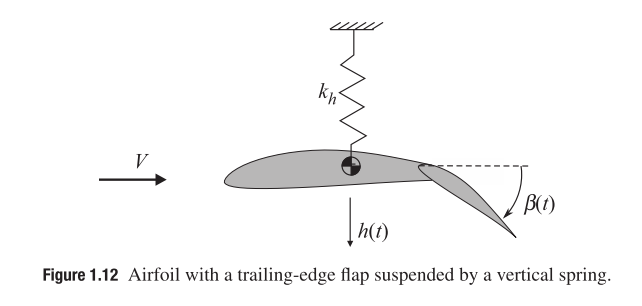

Written by:

    Rafael Palacios (r.palacios@imperial.ac.uk)

Latest update:

     April 2024

clear all

% Define coefficients
mu_a_overV=2;  % (\mu_a)/(V)
mu_b=1;
omega_h=4;

% Compute state-space matrices;
A=[[0 1]; [-omega_h^2 -mu_a_overV]];
B=[0; -mu_b];
C=[1 0];    % Output is vertical position (plunge).
D=[];

% Build state-space system
sys=ss(A,B,C,D);

Write the transfer function for the current parameters:

tf(sys)  % Output transfer function

ans =
 
        -1
  --------------
  s^2 + 2 s + 16
 
Continuous-time transfer function.
Model Properties


Plot the frequency-response function in log scale

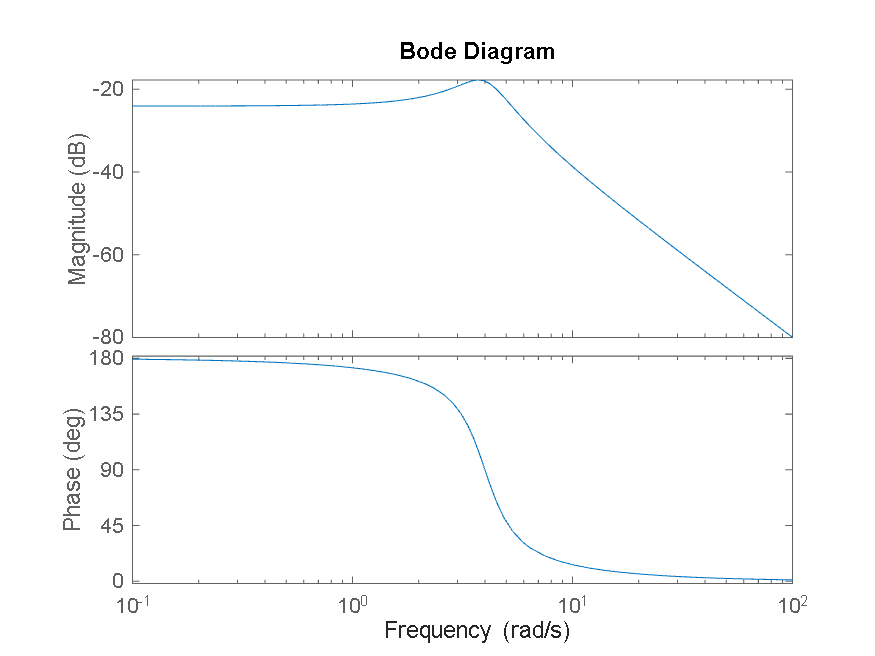

figure(1)
bode(sys);

Plot impulse response for 4 cycles

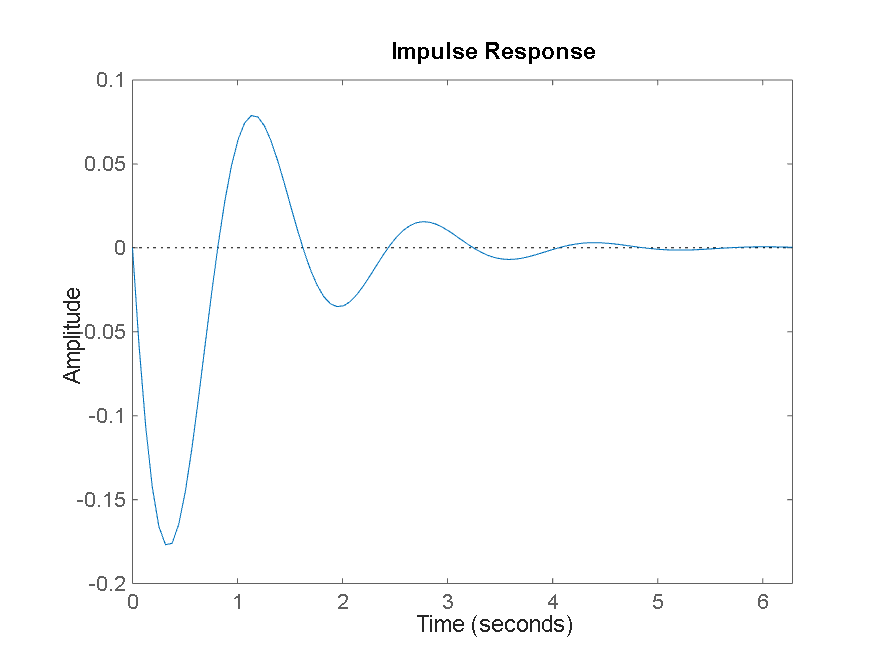

figure(2)
impulse(sys, 4*2*pi/omega_h);

Plot eigenvalues of the system for varying velocity 

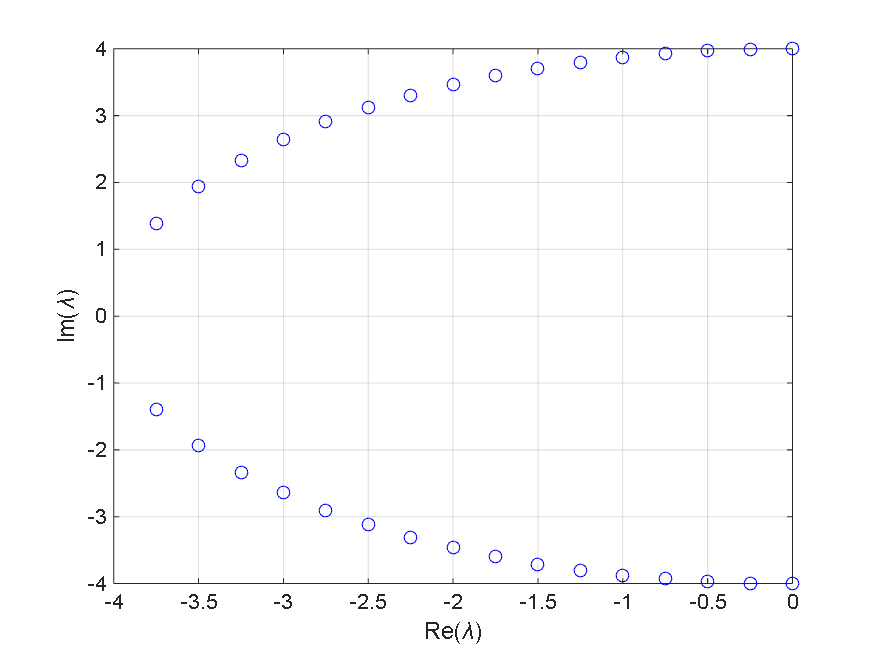

figure(3)
for mu_a_overV=0:0.5:7.5;
    A=[[0 1]; [-omega_h^2 -mu_a_overV]];
    sys=ss(A,B,C,D);
    plot(real(eig(sys)),imag(eig(sys)),'bo'), hold on, grid on
end
xlabel('Re(\lambda)'),ylabel('Im(\lambda)')